**Load paths**

start_toolkit

### **Preparing for Graph Theory**

**Compute connectivity matrix**

% connectivity matrix: how each node connects to other nodes
A = G.getConnectivityMatrix

**Create a network graph**

%translate the connectivity matrix into a graph structure
g = graph(A)
g.Edges(1:5,:)
figure
plot(g)

**Compute centrality metric**

cdegree = centrality(g, 'degree')
G.plot('highlightnode',nodeID(cdegree>2))

### **Other  simulation methods**

Method using the binary result file

B3 = G.getBinComputedAllParameters 
H3 = G.getComputedTimeSeries

Method using the ENepanet function (fastest)

H4 = G.getComputedTimeSeries_ENepanet

### **Multi-species chemical reactions**

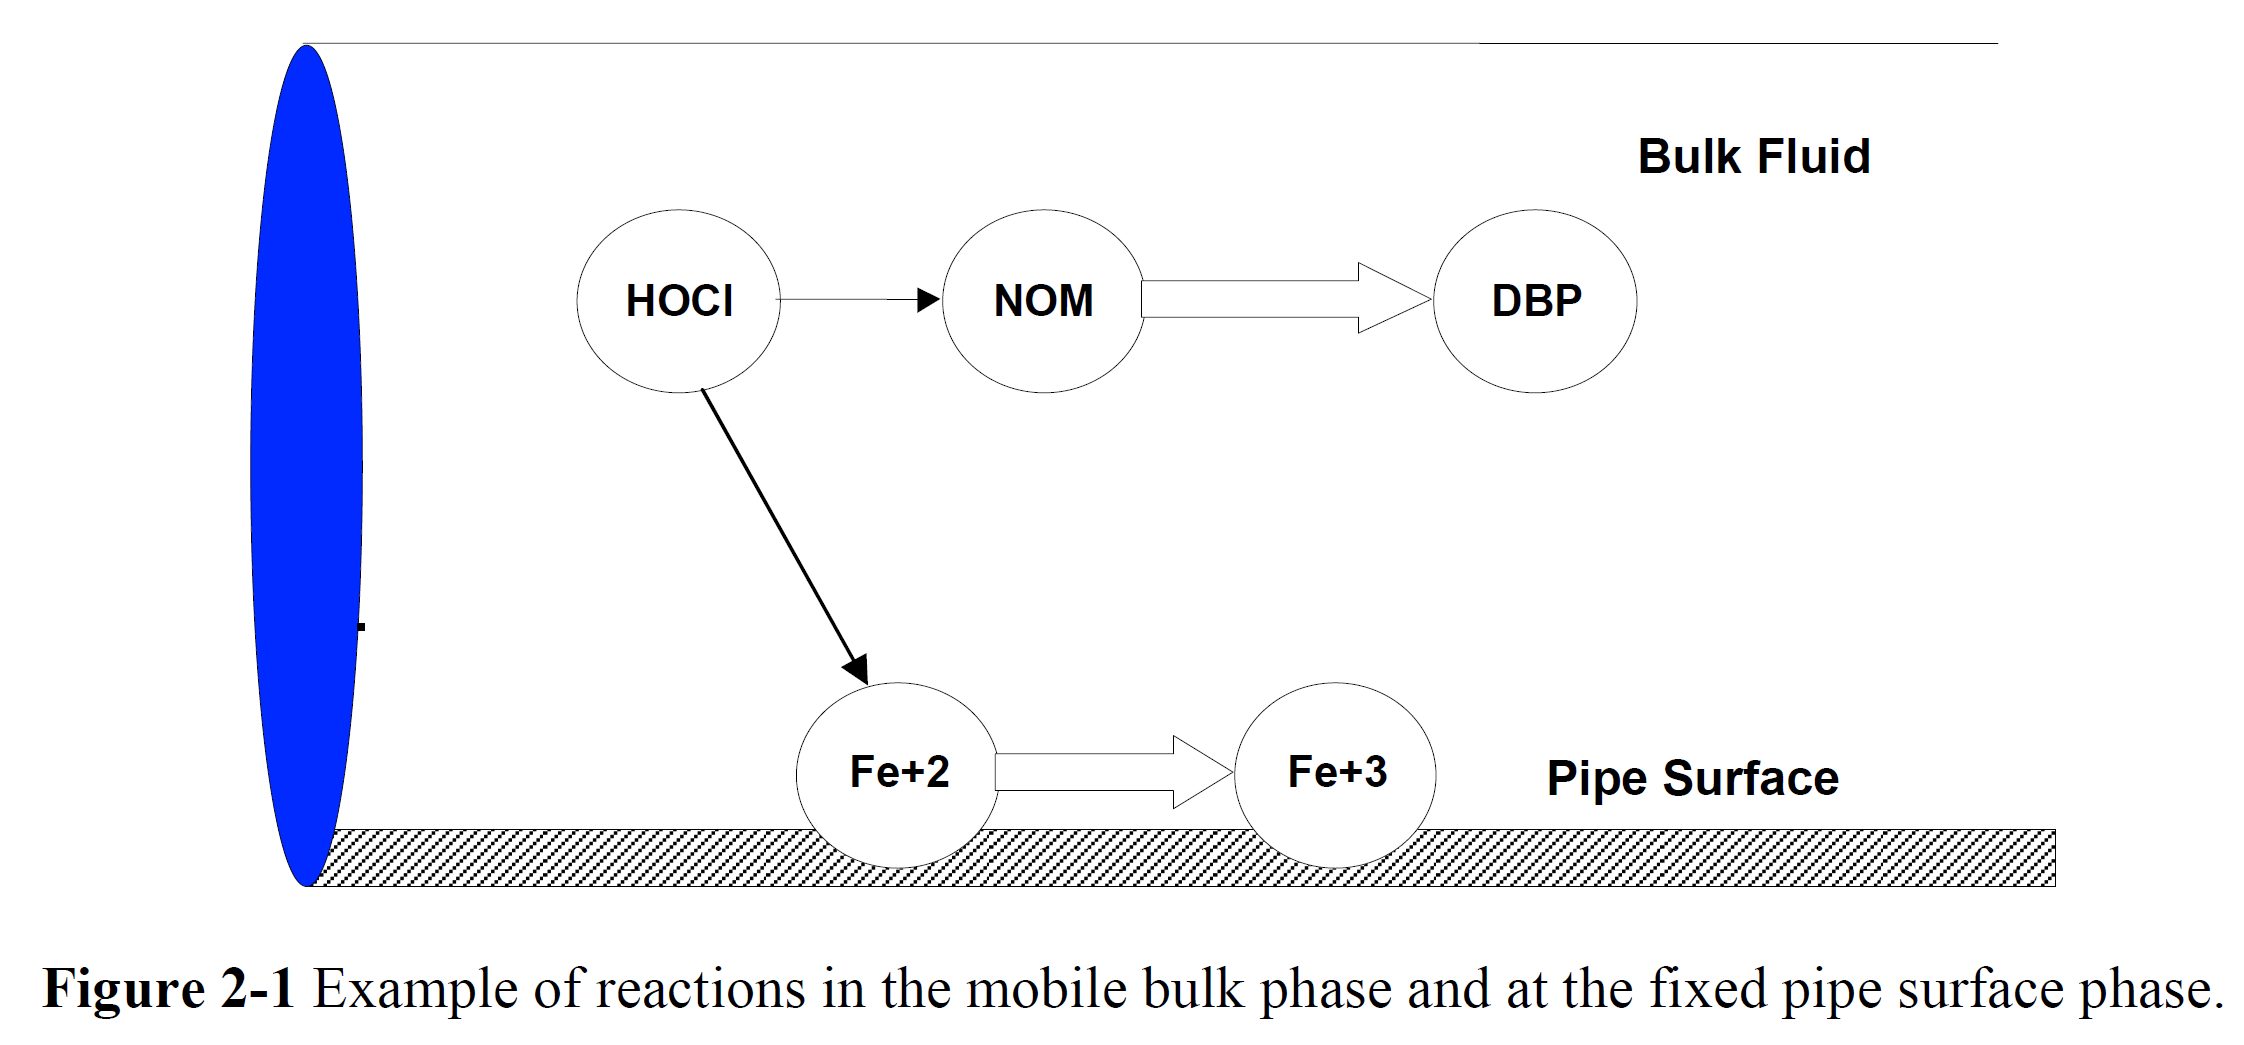

Reactions in water can be described using a set of Differential Algebraic Equations (DAE):


$$\frac{dx_b}{dt}=f(x_b,x_s,z_b,z_s)$$



$$\frac{dx_s}{dt}=g(x_b,x_s,z_b,z_s)$$



$$0=h(x_b,x_s,z_b,z_s)$$


These equations describe most of the reactions in water distribution systems. The solution methodology follows the following steps:

- Split the pipes into segments

- Solve the reaction equations for each segment

- Compute the advection (movement based on flows)

- Mix the bulk concentrations with the pipe wall concentrations 

- Recompute segmens

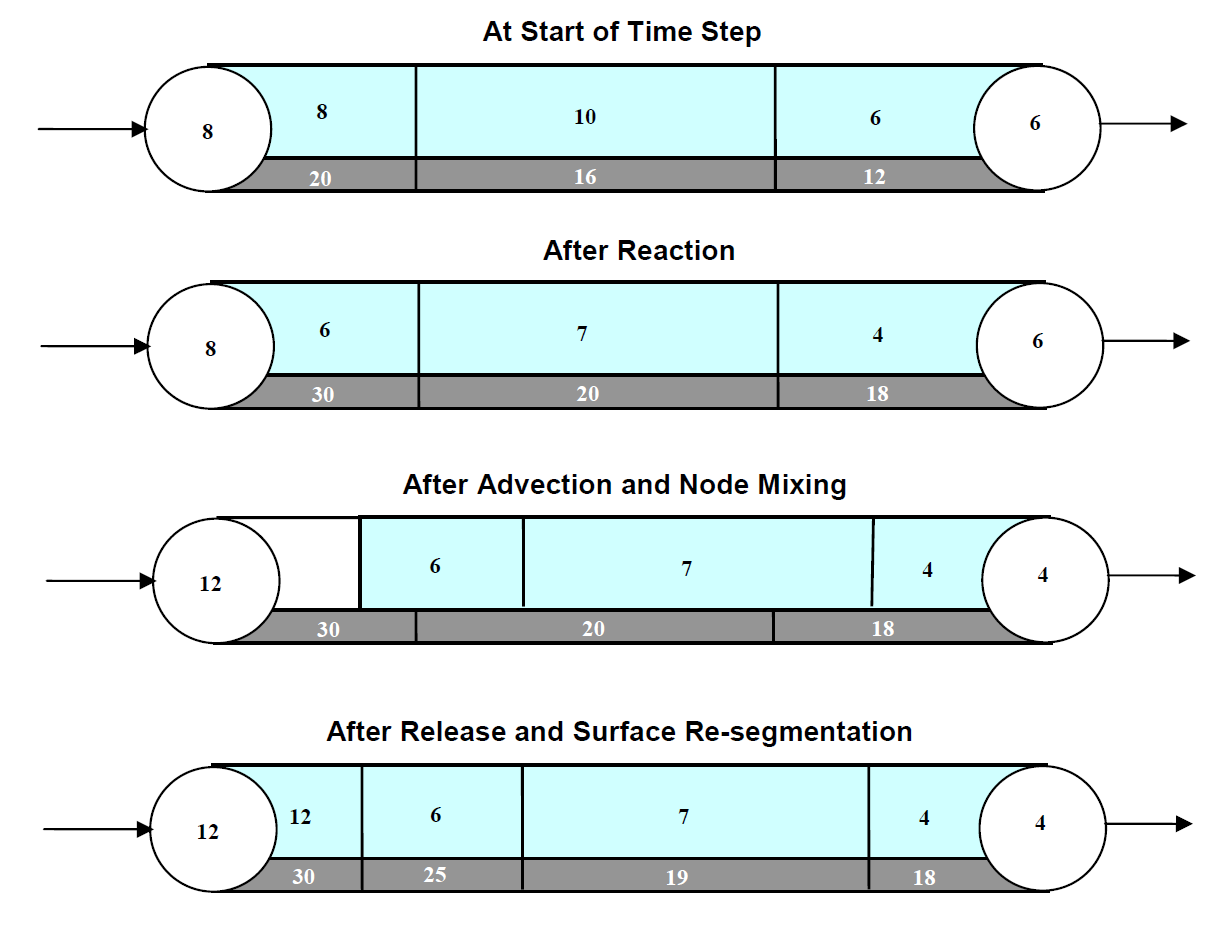

The set of diferential equations can be solved using an explicit method, e.g. **Runge-Kutta** or **Forward Euler** method.

** Chlorine reactions**

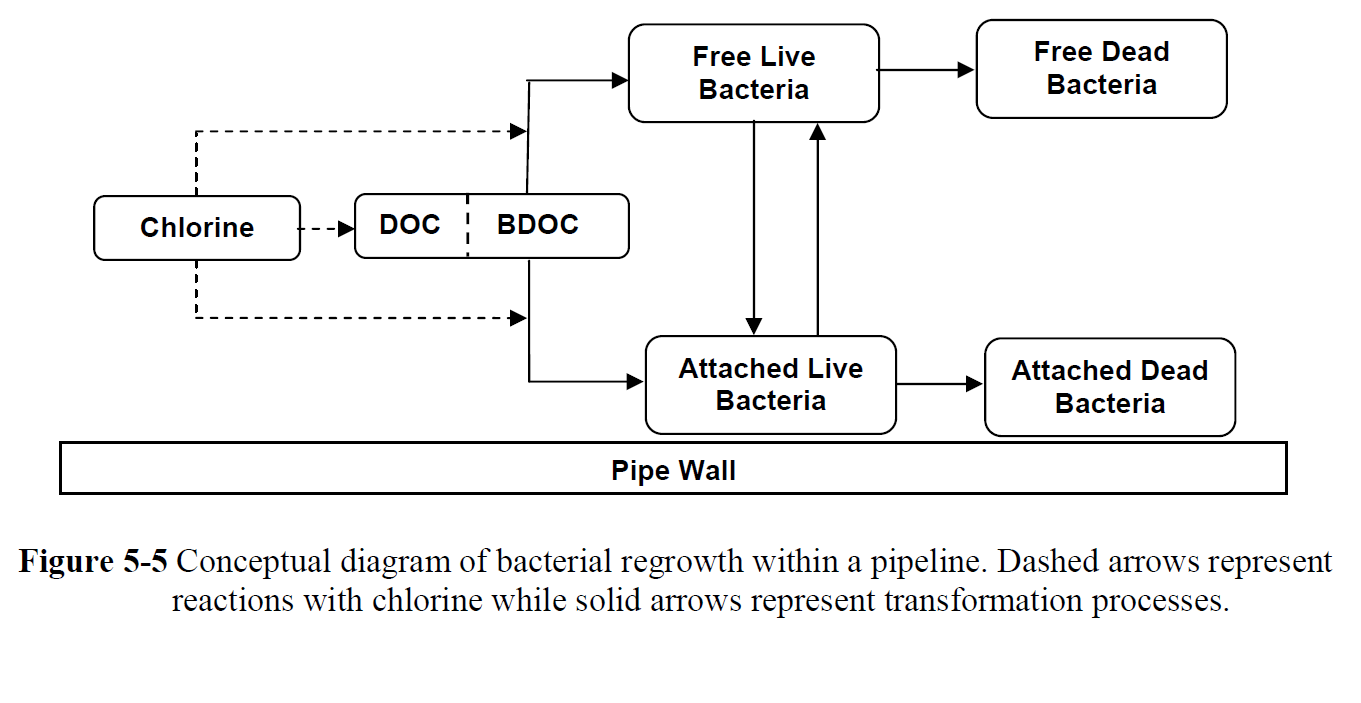

The most standard assumption is that Free Chlorine concentration is linear, i.e, 


$$\frac{dC(t)}{dt} = -k_bC(t)$$


Where $C(t)$ is the free chlorine concentration measured in $mg/L$.

% Example MSX file
fid = fopen('net2-cl2.msx','r')
c = fread(fid, inf, 'uint8=>char')'

How to load an MSX file

% Load EPANET-MSX file
G.loadMSXFile('net2-cl2.msx') % Load MSX file with reactions
qual_res_MSX = G.getMSXComputedQualitySpecie('CL2')
Q_msx = G.getMSXComputedQualityNode  % Compute water quality using MSX

Plot MSX species in MATLAB Figure

G.plotMSXSpeciesNodeConcentration(5,1)

**Another example**

% Get quality of specific nodes.
sensor_index = [2, 3, 5];
sensors_names = G.getNodeNameID(sensor_index)
QN = G.getMSXComputedQualityNode(sensor_index)

% Get quality of specific links.
QL = G.getMSXComputedQualityLink(sensor_index)

% Get species names.
type = G.getMSXSpeciesNameID;

% Get quality for specific species type (nodes and links).
for species = type
    MSX_comp = G.getMSXComputedQualitySpecie(species{1})
end

figure
G.plotMSXSpeciesNodeConcentration(3,1)

## **Monte Carlo Simulations**

**Introduction to Monte Carlo Simulations**

Monte Carlo simulation is a technique used to study how a model  responds to randomly generated inputs. It typically involves a  three-step process:

- Randomly generate “N” inputs (sometimes called scenarios).

- Run a simulation for each of the “N” inputs. Simulations are run on a computerized model of the system being analyzed.

- Aggregate and assess the outputs from the simulations. Common  measures include the mean value of an output, the distribution of output values, and the minimum or maximum output value.

**Simple example: Estimate π**

For a square 1 x 1 we can fit a circle with radious 0.5 in is centre. The area of this circle should be $\pi (\frac{1}{2})^2=\frac{\pi}{4}$. If we throw random points in the square, the fraction of these points should approximate this number.

npi = 39322200
% Create random points within a square 1 x 1
ppi = rand(npi, 2);
% Compute distance from point [0.5, 0.5]
rpi = sqrt((ppi(:,1)-0.5).^2+(ppi(:,2)-0.5).^2);
% What fraction of points are within the 0.5 radius?
fpi = sum(rpi <= 0.5) / npi; 
estimated_pi = fpi * 4
absolute_error = abs(pi - estimated_pi)

### **When are Monte Carlo Simulations needed?**

- Computing intervals and bounds in signals, when the parameters are uncertain

- Creating scenarios for solving various selection problems which cannot be solved by integer or mixed integer programming

For instance, if you want to decide where to install some sensors

Nnodes = 10000
Nsensors = 30
Combinations = nchoosek(Nnodes,Nsensors)

For reference, $10^{78} - 10^{82}$ are the **atoms in the known universe!**

### **Different types of uncertainties**

- Uniform, fixed bounds, good when we don't know reality

- Normal distribution, unbounded, good if we know distribution is normal. WARNING! Not all non-uniform distributions are normal!

N = 100000
unif_rand = rand(N,1); %[0,1]
norm_rand = randn(N,1); % any real number
unif_rand2 = 2*rand(N,1)-1; %[-1,1]
figure
subplot(1,3,1)
hist(unif_rand)
subplot(1,3,2)
hist(norm_rand)
subplot(1,3,3)
hist(unif_rand2)

How to randomize a vector $a$ with a bounded uncertainty ?

$a'=a+\eta a = (1+\eta) a$ , where $|\eta| < \bar{\eta}$ is the uncertainty

a = [8 8 6 10 12]
eta_bar = 0.2 % max uncertainty 20%
eta = (2*rand(1,length(a))-1)*eta_bar.*a
a2 = a + eta

**For non-random pseuso-random numbers, use RNG function! Useful for reproducing results.**

rng(20)
a = [8 8 6 10 12]
eta_bar = 0.2 % max uncertainty 20%
eta = (2*rand(1,length(a))-1)*eta_bar.*a
a2 = a + eta

### **Monte Carlo Simulations for EPANET **

How does uncertainty in the base demands, affects the pressures in a network?

Useful for:

- Fault diagnosis

- State estimation

- Forecasting

- Sensitivity studies

- Demonstrating robustness of solutions

**Initialize EPANET**

start_toolkit

**Prepare network for Monte Carlo Simulations**

% Load network
G = epanet('net2-cl2.inp')
% Number of simulations
Nsim = 50
% Get nominal base demands
base_demands = G.getNodeBaseDemands{1}
% 5% max uncertainty in base demands
eta_bar = 0.05

% initialize matrix to save MCS pressures
Pmcs = {};
Qmcs = {};

**Run the simulation and store the pressure results**

for i = 1:Nsim
    %compute new base demands
    delta_bd = (2*rand(1,length(base_demands))-1).*eta_bar.*base_demands;
    new_base_demands = base_demands + delta_bd;
    G.setNodeBaseDemands(new_base_demands);
    Pmcs{i} = G.getComputedHydraulicTimeSeries.Pressure;
    Qmcs{i} = G.getComputedQualityTimeSeries.NodeQuality;
    disp(['Epoch ',int2str(i)])
end

**How pressure fluctuates?**

node = 5;
figure
for i = 1:Nsim
    Pmulti(:,i) = Pmcs{i}(:,node);
    plot(Pmulti(:,i))
    hold on
end
title(['Pressure simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**Compute upper and lower bounds**

ub = max(Pmulti,[],2);
lb = min(Pmulti,[],2);
meanb = mean(Pmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Pressure bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**How quality fluctuates?**

node = 5;
figure
for i = 1:Nsim
    Qmulti(:,i) = Qmcs{i}(:,node);
    plot(Qmulti(:,i))
    hold on
end
title(['Quality simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Quality (mg/L)')

**Compute upper and lower bounds**

ub = max(Qmulti,[],2);
lb = min(Qmulti,[],2);
meanb = mean(Qmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Quality bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')


### **How pressure changes during fire-fighting?**

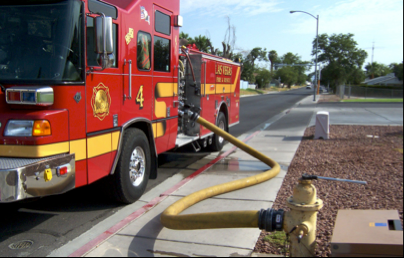

When flow is increased within the network, e.g., due to fire-fighting, the pressure changes near that location. Investigate this change, at node '32'.

G = epanet('Net1.inp');
nodeID = {'32'};
figure
G.plot('highlightnode', nodeID)

**During fire-fighting, the base demand may increase up to x5. Will there be sufficient pressure?**

idx = G.getNodeIndex(nodeID)
bd = G.getNodeBaseDemands{1}(idx)

demand_multi = 8 % demand multiplicator

d32 = bd *(1:demand_multi) % create the different demands
 
p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

**Plot demand vs pressure**

figure 
plot(d32, p32min,'x-')
grid on
xlabel('Base demand (m^3/h)')
ylabel('Pressure (psi)')

How about those negative pressures?

**Pressure Driven Simulations**

When the pressure is low, it should approximate zero. This is not the default mode of operation in EPANET. However, it's easy to set it up:

type = 'PDA';
pmin = 0;
preq = 0.1;
pexp = 0.5;
G.setDemandModel(type, pmin, preq, pexp)

Let's try this again

demand_multi = 10 % demand multiplicator
d32 = bd *(1:demand_multi) % create the different demands

p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

figure 
plot(d32, p32min,'x-')
grid on


### How to simulate a contamination event

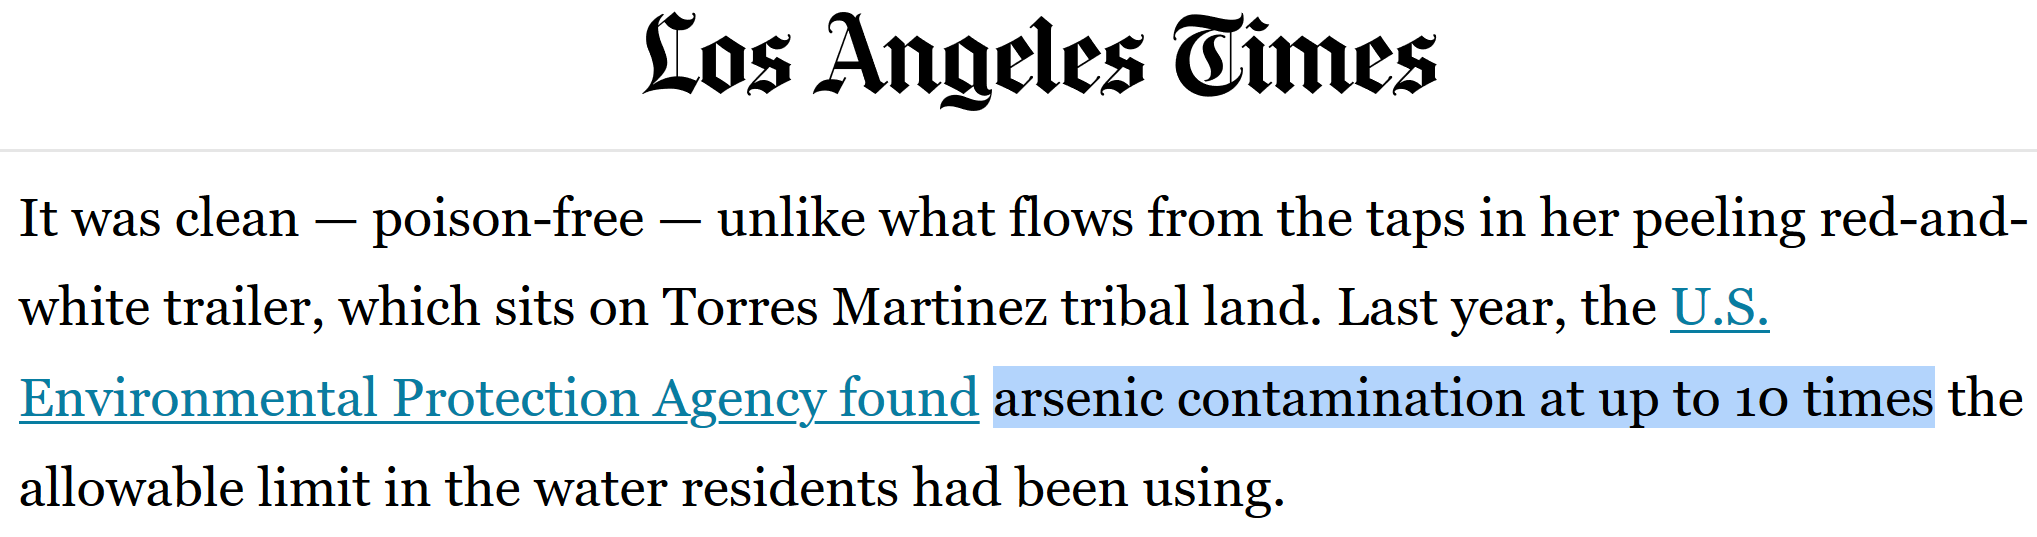

**Create an arsenite contamination event**

G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file
G.loadMSXFile('Arsenite.msx'); % Load MSX file

Prepare the simulations

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'};
sensor_index = G.getNodeIndex(sensor_id);

figure
G.plot('highlightnode', sensor_id,'nodes', 'yes', 'fontsize', 4);

% Simulation Setup
t_d = 5; % days
G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days
G.setMSXTimeStep(3600) 

A contamination scenario needs a location (node), a contaminant concentration and a time profile (start and end time)

injection_node = {'JUNCTION-23'}
injection_conc = 0.05
injection_start_time = 150 
figure
G.plot('highlightnode', injection_node);

**Initialize the contamination vector (binary)**

as3_pat = zeros(1, t_d*48); % initialize the vector
as3_pat(injection_start_time:end) = 1; % create the injection pattern 

**Simulate the contamination of water with arsenite**

% Specify Arsenite injection source
G.setMSXSources(injection_node, 'AsIII', 'Setpoint', injection_conc, 'AS3PAT'); 
% Set pattern for injection
G.setMSXPattern('AS3PAT',as3_pat);
% Solve hydraulics and MSX quality dynamics
Qmsx = G.getMSXComputedQualityNode(sensor_index); 

**Plot the results**

for i = 1:5
    figure
    plot(Qmsx.Time/3600, Qmsx.Quality{i})
    legend('Chlorine','As3', 'As5')
    title(sensor_id(i))
end

### **Monte Carlo simulations for contamination detection**

**Initialize the simulation**

rng(1)

%% Load EPANET Network and MSX
G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file
G.loadMSXFile('Arsenite.msx'); % Load MSX file

% Sensor locations
sensor_id = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'}
sensor_index = G.getNodeIndex(sensor_id);

%% Simulation Setup
t_d = 5 % days
G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;

G.setMSXTimeStep(3600)

**Setup uncertainties**

%% Scenarios
Ns = 20; % Number of scenarios to simulate
u_p = 0.20 % pattern uncertainty
u_r = 0.20 % roughness coefficient uncertainty

**Create the scenarios - first without contamination, to compute the bounds**

max_inj_conc = 0.0
inj_start_time = 2*48 % after day 2 (Dt = 30min)
inj_duration = 24 % maximum duration of 12 hours
% Injection location, magnitude, start time, duration 
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*rand(Ns,1), randi(48,Ns,1)+inj_start_time, randi(inj_duration,Ns,1)] 

**Run epochs**

for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    % Randomize injection
    %G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', inj_sc(i,2), 'AS3PAT'); % Specify Arsenite injection source
    %as3_pat = zeros(1, t_d*48);
    %as3_pat(inj_sc(i,3):(inj_sc(i,3)+inj_sc(i,4))) = 1; % 
    %G.setMSXPattern('AS3PAT',as3_pat); % Set pattern for injection
    QQ{i} = G.getMSXComputedQualityNode(sensor_index); % Solve hydraulics and MSX quality dynamics
    %G.setMSXSources(node_id(inj_sc(i,1)), 'AsIII', 'Setpoint', 0, 'AS3PAT'); % Reset injection source
end

**Plot the results without contaminations**

figure
for i = 1:Ns
    for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, QQ{i}.Quality{j}(:,1),'-','Color',[0,0.7,0.9]); hold on; grid on
       Qtable{j}(:,i) = QQ{i}.Quality{j}(:,1);
    end
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

**Compute the intervals for each sensor**

for j = 1:length(sensor_index)
    % Upper Bound
    UBQ(:,j) = max(Qtable{j},[],2); 
    % Lower Bound    
    LBQ(:,j) = min(Qtable{j},[],2);
end

**Plot the intervals**

figure
for j = 1:length(sensor_index)
       subplot(5,1,j)
       plot(QQ{i}.Time/24/60/60, UBQ(:,j),'r-'); 
       hold on; 
       plot(QQ{i}.Time/24/60/60, LBQ(:,j),'r-');

       % plot the contamination event simulated earier
       plot(Qmsx.Time/24/60/60, Qmsx.Quality{j}(:,1), 'b-')
       grid on
end
for i = 1:length(sensor_index)
   subplot(5,1,i)
   title(sensor_id{i})
   ylabel('Cl_2 (mg/L)')
   xlabel('Time (days)')
end

### **Contamination detection**

Compare what the model predicts, with what the (chlorine) sensors measure. If the difference is significantly larger, then put a fault warning.


$$e = y - \hat{y}$$


if $e > \bar{\epsilon}$ then fault flag $\phi(k) = 1$

figure
for j = 1:length(sensor_index)   
    % difference between the lower bound and the measured value
    e = LBQ(:,j) - Qmsx.Quality{j}(:,1);
    % create the \phi signal by putting 1 when the error is > 0
    phi = e>0;

    % plot the results
    subplot(5,1,j)
    plot(Qmsx.Time/24/60/60, phi, 'r-')
    title(sensor_id{i})
    ylabel('\phi')
    xlabel('Time (days)')
end

### **Sensor placement for quality monitoring**

Large-scale networks are difficult to monitor, and it is not possible to have sensors everywhere in the system, mainly due to costs. For this reason, we need to select the best locations to install sensors, in order to guarantee certain criteria, such as:

- Network coverage

- Detection delay

- Impact (e.g., number of people affected)

Sensor placement requires the following steps:

- Create simulation scenarios of contamination events

- Execute the simulation scenarios

- Measure the impact

- Formulate and solve an optimization problem

- If multiple objectives, costruct the Pareto front and select one solution

rng(1)

%% Load EPANET Network and MSX
G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

%% Simulation Setup
t_d = 5 % days
G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;
Nnodes = G.getNodeCount;

**Setup uncertainties**

%% Scenarios
Ns = 50; % Number of scenarios to simulate
u_p = 0.2 % pattern uncertainty
u_r = 0.2 % roughness coefficient uncertainty

**Create the scenarios - first without contamination, to compute the bounds**

max_inj_conc = 10.0
inj_start_time = 1 % after day 2 (Dt = 30min)
inj_duration = 24 % maximum duration of 12 hours
% Injection location, magnitude, start time, duration 
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*ones(Ns,1), (inj_start_time)*ones(Ns,1), inj_duration*ones(Ns,1)] 

**Create the coverage matrix**

The coverage matrix is a binary matrix, where earh row is a scenario, and each column is a node. If a certain contamination scenario affects (can reach) a certain node, the flag is true, else false.

K = zeros(1,Nnodes);
for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    c = zeros(1,Nnodes);
    c(inj_sc(i,1)) = inj_sc(i,2);
    G.setNodeInitialQuality(c);
    
    qsp = G.getComputedTimeSeries.NodeQuality;
    K(i,:) = max(qsp)>0;
end

**Decide which nodes are best for installing a sensor**

- Avoid having sensors to monitor the same area

- Some scenarios affect all nodes, and some others, may not affect any node.

This means: select those columns that have ones, so that there is at least one positive flag '1' in as many rows as possible

$Y$ is the vector of "scenario observability" (number of scenarios $\times$ 1)

$u$ is the solution, a binary vector (number of nodes $\times$ 1)

$K$ is the coverage matrix (number of scenarios $\times$ number of nodes)


$$Y = Ku$$


The optimizaiton problem is formed in its simplest form as


$$\arg\max f(u)$$



$$u\in\{0,1\}^{N}}$$



$$\sum u_i = m$$


Where $f(u)$ is the objective function.  The simplest function is "the percentage of scenarios which can be 'detected' by the sensors".

We can have multiple functions, and in that case, we need multi-objective optimization.

% random selection of nodes
rng(1)
Nsensors = 5 % number of sensors
total_combinations = nchoosek(Nnodes, Nsensors) % 275 Millions for 5 sensors in 129 nodes

% Create a random solution
s = randperm(Nnodes, Nsensors) % return random
% solution
u = zeros(Nnodes, 1);
u(s) = 1;
% compute output
Y = K*u
% how many non-zero elemenets in Y?
perc_coverage = sum(Y>0)/double(Ns)*100

**Discussion: Number of scenarios**

- How many scenarios should we create?

- In general, the more scenarios, the more robust your solution

- Simulate contamination events at different time steps

- Simulate different hydraulic conditions

% Table of all scenarios vs nodes, with flag = 1 
% if the contaminant is observed at that node 
load Kall.mat 
[Nsall, ~] = size(Kall)

**Repeat solution computation for the larger dataset**

rng(1)
Nsensors = 5 % number of sensors

% Create a random solution
s = randperm(Nnodes, Nsensors) % return random
% solution 
u = zeros(Nnodes, 1);
u(s) = 1;
% compute output
Y = Kall*u;
% how many non-zero elemenets in Y?
perc_coverage = sum(Y>0)/double(Nsall)*100

**Randomized solutions for multiple sensors**

How many sensors to install? Let's create a lot of random solutions

rng(1)
epochs = 1000
maxsensors = 20
fx = [];
for i = 1:epochs
    ns = randi(maxsensors);
    s = randperm(Nnodes, ns);
    u = zeros(Nnodes, 1);
    u(s) = 1;
    Y = Kall*u;
    fx(i,:) = [ns, sum(Y>0)/double(Nsall)*100];
end

Plotting the results

figure
plot(fx(:,1), fx(:,2),'x')
grid on
hold all
maxfx=[];
for i = 1:maxsensors
    maxfx(i,:)= [i max(fx(fx(:,1)==i,2))];
end
plot(maxfx(:,1), maxfx(:,2),'r-')

**Discussion: Is this a valid way of solving problems?**

**How can we solve this optimization problem?**

- Integer/Mixed Integer Quadradic Programming

- Evolutionary Optimization (Single-objective)

- Evolutionary Optimization (Multi-objective)

rng(2)
Nsensors = 5
[Nsall, Nnodes] = size(Kall)
gafunc = @(x) calc_score(x,Kall,Nsall)
[x,fval] = ga(gafunc, Nsensors,[],[],[],[],ones(Nsensors,1),Nnodes*ones(Nsensors,1));
sensors = round(x)
sensorsID = G.getNodeNameID(sensors)
score = -fval

Plot the location of the sensors

G.plot('highlightnode',sensorsID)

**What happens when we have multiple objectives**? 

- Minimize detection time and maximize coverage

- No single optimal solution

- Need to compute a pareto front of solutions

% Table of all scenarios vs nodes, with flag = 1 
% if the contaminant is observed at that node 
load Kall.mat 
% Table of all scenarios vs nodes, detection time in minutes
load Tall.mat

**Solve the multi-objective optimization using the NSGA-II method**

rng(12)
Nsensors = 5
[Nsall, Nnodes] = size(Kall)
gamultifunc = @(x) calc_score_multi(x,Kall,Nsall,Tall)
[x,fval] = gamultiobj(gamultifunc, Nsensors,[],[],[],[],ones(Nsensors,1),Nnodes*ones(Nsensors,1))
sensors = round(x)

**Plot the results and the Pareto Front**

figure
plot(100+fval(:,1),fval(:,2)/60,'o')
grid on
xlabel('Non-covered nodes %')
ylabel('Detection delay (hours)')

**Function definitions**

Single objective function

function gafunc = calc_score(x, Kall, Nsall)
    gafunc = -sum(max(Kall(:,round(x)),[],2))/Nsall*100;
end

Multi-objective function

function gamultifunc = calc_score_multi(x, Kall, Nsall,Tall)
    gamultifunc(1) = -sum(max(Kall(:,round(x)),[],2))/Nsall*100;
    gamultifunc(2) = median(min(Tall(:,round(x)),[],2));
end

**Leakage Detection**

Let's create a dataset with a leakage

Dsim = 100 % Simulation days
K = (1:288*Dsim)'; % time steps of simulation

% compute the fourier values
A6 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))']
% create weekly periodicity 
s = A6*rcoef
% create noise
eta = random(pdlog,length(K),1);
y = s.*(1+eta)

figure
plot(y)
grid on
xlim([6624 8306])
ylim([6.6 65.9])

**Simulate a leakage event**

leakSize = 5 % m3/h
leakDay = 60.5
T0 = leakDay * 288;
T1 = T0 + 288*7;
phi = zeros(length(K),1);
phi(T0:T1) = leakSize;
y2 = y + phi

figure
plot(y2)
grid on
xlim([15502 20656])
ylim([6.3 66.7])

**Minimum Night Flow Analysis**

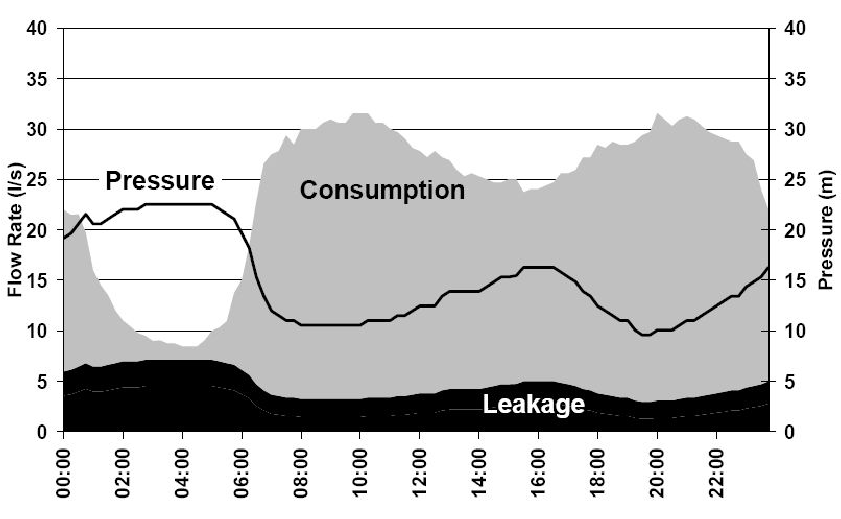

- Basic idea is that each night the uncertainty is low

- Demand is low

- Pressure is high

- Easier to detect leakages

% compute the minimum flow for each day
Y = reshape(y2,288,100)
MF = min(Y)
grid on
plot(MF)
grid on
line([100,0],[9,9])

**Detecting changes**

- Change detection algorithms

- Limit checking, change in mean

- Cumulative Sum (CUSUM)


% Find change points
[changeIndices,segmentMean] = ischange(MF,'Threshold',3);

% Visualize results
clf
plot(MF,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentMean,'Color',[64 64 64]/255,'DisplayName','Segment mean')

% Plot change points
x = repelem(find(changeIndices),3);
y3 = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y3,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend
clear segmentMean x y3


Limit checking, the most simple detection algorithm

threshold = 9
alert = MF > threshold

figure
plot(alert, 'r-')

A different approach would be to take a window of minimum (night) flows, and compare them with the new minimum flow. If it exceeds a precalculated distance, the issue an alert.